# Compare Fits in Curve Fitter App

## Interactive Curve Fitter Workflow

The next topics fit census data using polynomial equations up to the sixth degree, and a single-term exponential equation. The steps demonstrate how to:

- Load data and explore various fits using different library models.

- Search for the best fit by:

- Comparing graphical fit results

- Comparing numerical fit results including the fitted coefficients and goodness-of-fit statistics

- Export your best fit results to the MATLAB® workspace to analyze the model at the command line.

- Save the session and generate MATLAB code for all fits and plots.

## **Loading Data and Creating Fits**

You must load the data variables into the MATLAB workspace before you can fit data using the Curve Fitter app. For this example, the data is stored in the MATLAB file `census.mat`.

    1. Load the data.

clear
load census

The workspace contains two new variables.

- `cdate` is a column vector containing the years 1790 to 1990 in 10-year increments.

- `pop` is a column vector with the US population figures that correspond to the years in `cdate`.

2. Open the Curve Fitter app.

curveFitter

    3. On the **Curve Fitter** tab, in the **Data** section, click **Select Data**. In the Select Fitting Data dialog box, select the variable names `cdate` and `pop` from the **X data** and **Y data** lists, respectively.The Curve Fitter app creates and plots a default fit to the X input (or predictor) data and the Y output (or response) data. The default fit is a linear polynomial fit type. Observe the fit settings display in the **Fit Options** pane. The fit is a first-degree polynomial

    4. In the **Fit Options** pane, change the fit to a second-degree polynomial by selecting `2` from the **Degree** list.The Curve Fitter app plots the new fit. The Curve Fitter app calculates a new fit when you change fit settings because **Auto** is selected by default. If refitting is time consuming, as is sometimes the case for large data sets, you can turn off the automatic behavior. On the **Curve Fitter** tab, in the **Fit** section, select **Manual**.The Curve Fitter app displays results of fitting the census data with a quadratic polynomial in the **Results** pane, where you can view the library model, fitted coefficients, and goodness-of-fit statistics.

    5. Change the name of the fit. In the **Table Of Fits** pane, double-click `untitled fit 1` in the **Fit name** column and type `poly2`.

    6. Display the residuals. On the **Curve Fitter** tab, in the **Visualization** section, click **Residuals Plot**.The residuals indicate that a better fit might be possible. Therefore, continue exploring various fits to the census data set.

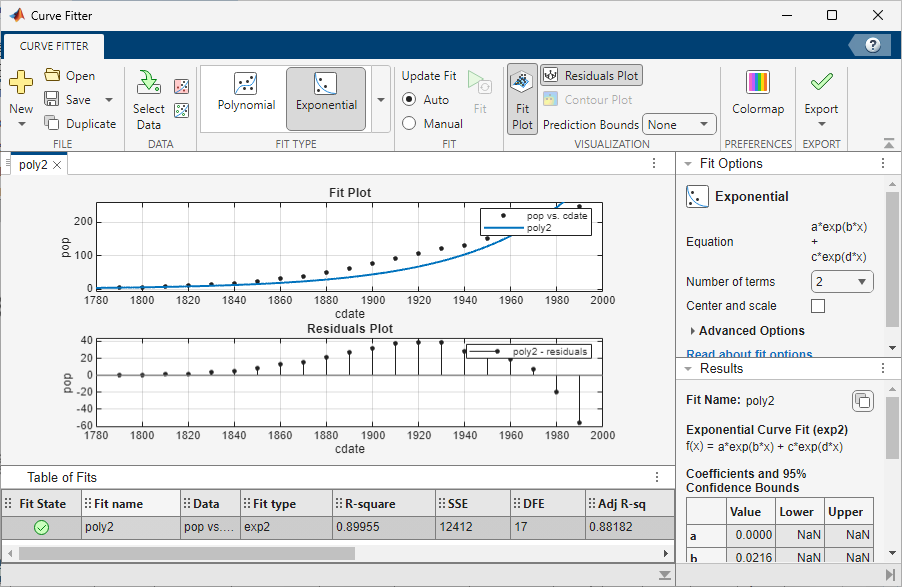

    7. Add new fits to try the other library equations.

        a. Right-click the fit in the **Table Of Fits** pane, and select **Duplicate "poly2"**. Alternatively, on the **Curve Fitter** tab, in the **File** section, click **Duplicate**.

**        Tip: **For fits of a given type (for example, polynomials), duplicate a fit instead of creating a new fit because copying a fit requires fewer steps. The duplicated fit contains the same data selections and fit settings.

        b. Change the polynomial **Degree** to `3` and rename the fit `poly3`.

        c. When you fit higher degree polynomials, the **Results** pane displays this warning. 

`        Equation is badly conditioned. Remove repeated data points or try centering and scaling.`

Normalize the data by selecting the **Center and scale** check box in the **Fit Options** pane.

        d. Repeat steps a and b to add polynomial fits up to the sixth degree. Then add an exponential fit. On the **Curve Fitter** tab, in the **File** section, click **New** and select **New Fit**. In the **Fit Type** section, click the arrow to open the gallery, and click **Exponential** in the **Regression Models** section.

        e. For each new fit, look at the **Results** pane information, and the residuals plot in the app.The residuals from a good fit should look random with no apparent pattern. A pattern, such as a tendency for consecutive residuals to have the same sign, can be an indication that a better model exists.

#### **About Scaling**

The warning about scaling arises because the fitting procedure uses the `cdate` values as the basis for a matrix with very large values. The spread of the `cdate` values results in a scaling problem. To address this problem, you can normalize the `cdate` data. Normalization scales the predictor data to improve the accuracy of the subsequent numeric computations. For example, you can normalize `cdate` by centering and scaling the data to have zero mean and unit standard deviation.

(cdate - mean(cdate))./std(cdate)

**Note: **Because the predictor data changes after normalizing, the values of the fitted coefficients also change when compared to the original data. However, the functional form of the data and the resulting goodness-of-fit statistics do not change. Additionally, the data is displayed in the Curve Fitter app plots using the original scale.

**Explora el resto del ejemplo aquí **[https://la.mathworks.com/help/curvefit/fit-comparison-in-curve-fitting-app.html](https://la.mathworks.com/help/curvefit/fit-comparison-in-curve-fitting-app.htmlhttps://la.mathworks.com/help/curvefit/fit-comparison-in-curve-fitting-app.html)